# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

You should see output similar to the following:

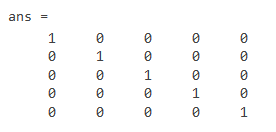

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

### 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

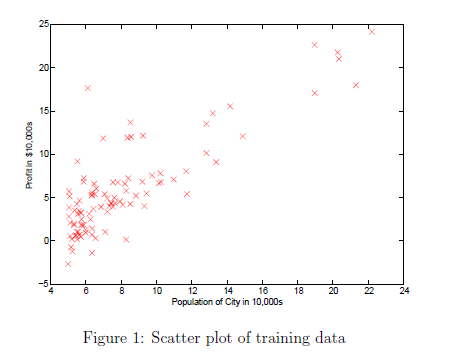

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

### 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### 2.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

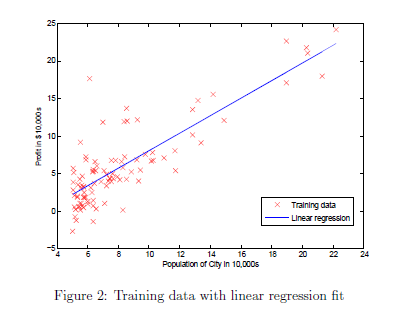    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure

% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);
predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

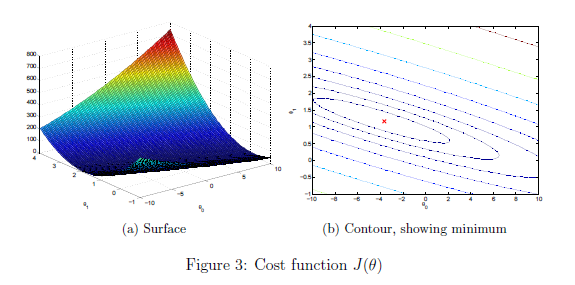

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

The remainder of this script has been set up to help you step through this exercise.

### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

#### Add the bias term

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================

instance = ([1650,3] - mu)./sigma
price = theta' * [1,instance]';

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

#### **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

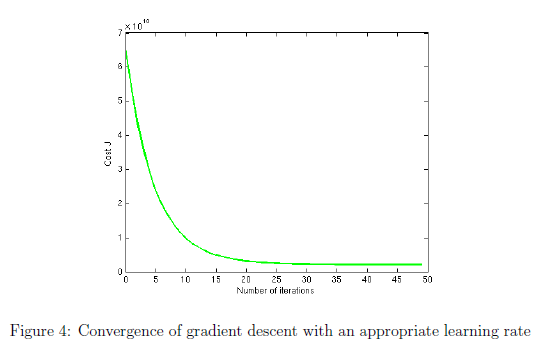

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

% Run gradient descent:
% Choose some alpha value
alpha = 1;
num_iters = 50;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

new_theta =      0
     0
     0


sum = 0

sum = -2.5526e+03

sum = -4.6583e+03

sum = -7.0136e+03

sum = -8.4945e+03

sum = -1.1941e+04

sum = -1.3855e+04

sum = -1.5865e+04

sum = -1.7135e+04

sum = -1.8488e+04

sum = -2.0036e+04

sum = -2.1568e+04

sum = -2.3783e+04

sum = -2.5889e+04

sum = -3.0357e+04

sum = -3.2016e+04

sum = -3.4887e+04

sum = -3.6802e+04

sum = -3.8078e+04

sum = -4.1269e+04

sum = -4.5093e+04

sum = -4.6707e+04

sum = -4.8334e+04

sum = -4.9885e+04

sum = -5.1544e+04

sum = -5.5207e+04

sum = -5.6802e+04

sum = -5.9767e+04

sum = -6.2761e+04

sum = -6.5793e+04

sum = -6.7707e+04

sum = -6.9940e+04

sum = -7.1025e+04

sum = -7.3035e+04

sum = -7.6736e+04

sum = -7.8561e+04

sum = -8.0156e+04

sum = -8.1624e+04

sum = -8.3826e+04

sum = -8.7330e+04

sum = -8.9162e+04

sum = -9.1514e+04

sum = -9.3620e+04

sum = -9.5624e+04

sum = -9.7533e+04

sum = -9.8681e+04

sum = -1.0060e+05

sum = -1.0212e+05

sum = 0

sum = -331.8571

sum = 729.8380

sum = -453.6542

sum = 635.8420

sum = -3.6976e+03

sum = -3.6599e+03

sum = -2.4795e+03

sum = -1.5626e+03

sum = -505.6987

sum = 481.1831

sum = 598.1546

sum = 600.0522

sum = 893.4143

sum = -1.3033e+04

sum = -1.1503e+04

sum = -1.2585e+04

sum = -1.0945e+04

sum = -9.7177e+03

sum = -1.2161e+04

sum = -1.7118e+04

sum = -1.6643e+04

sum = -1.6412e+04

sum = -1.5638e+04

sum = -1.5558e+04

sum = -2.4266e+04

sum = -2.2459e+04

sum = -2.0434e+04

sum = -2.2413e+04

sum = -2.3173e+04

sum = -2.4706e+04

sum = -2.4252e+04

sum = -2.2886e+04

sum = -2.2985e+04

sum = -2.8278e+04

sum = -2.7843e+04

sum = -2.6711e+04

sum = -2.5305e+04

sum = -2.5669e+04

sum = -3.5433e+04

sum = -3.5805e+04

sum = -3.4808e+04

sum = -3.5437e+04

sum = -3.6865e+04

sum = -3.4942e+04

sum = -3.3282e+04

sum = -3.2924e+04

sum = -3.1390e+04

sum = 0

sum = 570.9428

sum = 1.0419e+03

sum = 1.5688e+03

sum = 3.8460e+03

sum = 88.2149

sum = -1.9991e+03

sum = -1.5495e+03

sum = -1.2654e+03

sum = -962.7446

sum = -616.5240

sum = -2.2869e+03

sum = -1.7915e+03

sum = -1.3204e+03

sum = -1.2062e+04

sum = -1.1691e+04

sum = -1.4823e+04

sum = -1.1879e+04

sum = -1.1594e+04

sum = -1.5074e+04

sum = -1.9243e+04

sum = -1.8882e+04

sum = -1.6379e+04

sum = -1.6032e+04

sum = -1.7841e+04

sum = -1.7021e+04

sum = -1.6665e+04

sum = -1.6002e+04

sum = -1.5332e+04

sum = -1.4654e+04

sum = -1.4226e+04

sum = -1.0791e+04

sum = -7.6984e+03

sum = -9.8901e+03

sum = -9.0622e+03

sum = -1.1052e+04

sum = -1.0695e+04

sum = -1.0367e+04

sum = -1.2768e+04

sum = -1.6589e+04

sum = -1.8587e+04

sum = -1.4970e+04

sum = -1.4499e+04

sum = -1.6684e+04

sum = -1.6258e+04

sum = -1.4492e+04

sum = -1.6579e+04

sum = -1.6237e+04

h_i = 0

diff = -399900

J = 1.5992e+11

h_i = 0

diff = -329900

J = 2.6875e+11

h_i = 0

diff = -369000

J = 4.0492e+11

h_i = 0

diff = -232000

J = 4.5874e+11

h_i = 0

diff = -539900

J = 7.5023e+11

h_i = 0

diff = -299900

J = 8.4017e+11

h_i = 0

diff = -314900

J = 9.3933e+11

h_i = 0

diff = -198999

J = 9.7893e+11

h_i = 0

diff = -212000

J = 1.0239e+12

h_i = 0

diff = -242500

J = 1.0827e+12

h_i = 0

diff = -239999

J = 1.1403e+12

h_i = 0

diff = -347000

J = 1.2607e+12

h_i = 0

diff = -329999

J = 1.3696e+12

h_i = 0

diff = -699900

J = 1.8595e+12

h_i = 0

diff = -259900

J = 1.9270e+12

h_i = 0

diff = -449900

J = 2.1294e+12

h_i = 0

diff = -299900

J = 2.2193e+12

h_i = 0

diff = -199900

J = 2.2593e+12

h_i = 0

diff = -499998

J = 2.5093e+12

h_i = 0

diff = -599000

J = 2.8681e+12

h_i = 0

diff = -252900

J = 2.9321e+12

h_i = 0

diff = -255000

J = 2.9971e+12

h_i = 0

diff = -242900

J = 3.0561e+12

h_i = 0

diff = -259900

J = 3.1236e+12

h_i = 0

diff = -573900

J = 3.4530e+12

h_i = 0

diff = -249900

J = 3.5155e+12

h_i = 0

diff = -464500

J = 3.7312e+12

h_i = 0

diff = -469000

J = 3.9512e+12

h_i = 0

diff = -475000

J = 4.1768e+12

h_i = 0

diff = -299900

J = 4.2667e+12

h_i = 0

diff = -349900

J = 4.3892e+12

h_i = 0

diff = -169900

J = 4.4180e+12

h_i = 0

diff = -314900

J = 4.5172e+12

h_i = 0

diff = -579900

J = 4.8535e+12

h_i = 0

diff = -285900

J = 4.9352e+12

h_i = 0

diff = -249900

J = 4.9977e+12

h_i = 0

diff = -229900

J = 5.0505e+12

h_i = 0

diff = -345000

J = 5.1695e+12

h_i = 0

diff = -549000

J = 5.4709e+12

h_i = 0

diff = -287000

J = 5.5533e+12

h_i = 0

diff = -368500

J = 5.6891e+12

h_i = 0

diff = -329900

J = 5.7979e+12

h_i = 0

diff = -314000

J = 5.8965e+12

h_i = 0

diff = -299000

J = 5.9859e+12

h_i = 0

diff = -179900

J = 6.0183e+12

h_i = 0

diff = -299900

J = 6.1082e+12

h_i = 0

diff = -239500

J = 6.1656e+12

J = 6.5592e+10

theta = 	1.0e+05 *

    1.0212
    0.3139
    0.1624


new_theta = 	1.0e+05 *

    1.0212
    0.3139
    0.1624


sum = 0

sum = -1.8978e+03

sum = -3.4759e+03

sum = -5.1019e+03

sum = -6.2377e+03

sum = -8.6670e+03

sum = -9.8204e+03

sum = -1.1319e+04

sum = -1.2106e+04

sum = -1.2987e+04

sum = -1.4033e+04

sum = -1.4816e+04

sum = -1.6402e+04

sum = -1.7908e+04

sum = -2.0850e+04

sum = -2.2065e+04

sum = -2.4096e+04

sum = -2.5689e+04

sum = -2.6529e+04

sum = -2.8803e+04

sum = -3.1601e+04

sum = -3.2646e+04

sum = -3.3810e+04

sum = -3.4831e+04

sum = -3.5735e+04

sum = -3.8293e+04

sum = -3.9487e+04

sum = -4.1960e+04

sum = -4.4192e+04

sum = -4.6545e+04

sum = -4.7671e+04

sum = -4.9452e+04

sum = -5.0433e+04

sum = -5.1668e+04

sum = -5.4454e+04

sum = -5.5562e+04

sum = -5.6671e+04

sum = -5.7701e+04

sum = -5.9106e+04

sum = -6.1287e+04

sum = -6.2313e+04

sum = -6.4258e+04

sum = -6.5675e+04

sum = -6.6771e+04

sum = -6.8253e+04

sum = -6.9199e+04

sum = -7.0385e+04

sum = -7.1487e+04

sum = 0

sum = -246.7369

sum = 548.9213

sum = -268.0904

sum = 567.5314

sum = -2.4873e+03

sum = -2.4646e+03

sum = -1.5843e+03

sum = -1.0168e+03

sum = -328.6934

sum = 338.8105

sum = 398.5475

sum = 399.9067

sum = 609.5979

sum = -8.5609e+03

sum = -7.4407e+03

sum = -8.2058e+03

sum = -6.8410e+03

sum = -6.0327e+03

sum = -7.7728e+03

sum = -1.1401e+04

sum = -1.1094e+04

sum = -1.0929e+04

sum = -1.0419e+04

sum = -1.0375e+04

sum = -1.6457e+04

sum = -1.5104e+04

sum = -1.3416e+04

sum = -1.4891e+04

sum = -1.5481e+04

sum = -1.6382e+04

sum = -1.6020e+04

sum = -1.4785e+04

sum = -1.4846e+04

sum = -1.8830e+04

sum = -1.8566e+04

sum = -1.7780e+04

sum = -1.6792e+04

sum = -1.7024e+04

sum = -2.3101e+04

sum = -2.3310e+04

sum = -2.2486e+04

sum = -2.2909e+04

sum = -2.3690e+04

sum = -2.2198e+04

sum = -2.0831e+04

sum = -2.0609e+04

sum = -1.9504e+04

sum = 0

sum = 424.4980

sum = 777.4781

sum = 1.1412e+03

sum = 2.8877e+03

sum = 238.7279

sum = -1.0189e+03

sum = -683.6098

sum = -507.7628

sum = -310.7036

sum = -76.5280

sum = -929.6060

sum = -574.7692

sum = -238.0017

sum = -7.3116e+03

sum = -7.0398e+03

sum = -9.2549e+03

sum = -6.8046e+03

sum = -6.6167e+03

sum = -9.0955e+03

sum = -1.2147e+04

sum = -1.1914e+04

sum = -1.0124e+04

sum = -9.8958e+03

sum = -1.0881e+04

sum = -1.0309e+04

sum = -1.0042e+04

sum = -9.4890e+03

sum = -8.9897e+03

sum = -8.4634e+03

sum = -8.2117e+03

sum = -5.4719e+03

sum = -2.6757e+03

sum = -4.0226e+03

sum = -3.3994e+03

sum = -4.6074e+03

sum = -4.3594e+03

sum = -4.1289e+03

sum = -5.6600e+03

sum = -8.0383e+03

sum = -9.1575e+03

sum = -6.1672e+03

sum = -5.8502e+03

sum = -7.0460e+03

sum = -6.7146e+03

sum = -5.2607e+03

sum = -6.5549e+03

sum = -6.3086e+03

h_i = 1.0257e+05

diff = -2.9733e+05

J = 8.8403e+10

h_i = 8.2666e+04

diff = -2.4723e+05

J = 1.4953e+11

h_i = 1.1426e+05

diff = -2.5474e+05

J = 2.1442e+11

h_i = 5.4061e+04

diff = -1.7794e+05

J = 2.4608e+11

h_i = 1.5930e+05

diff = -3.8060e+05

J = 3.9094e+11

h_i = 1.1921e+05

diff = -1.8069e+05

J = 4.2359e+11

h_i = 8.0059e+04

diff = -2.3484e+05

J = 4.7874e+11

h_i = 7.5832e+04

diff = -1.2317e+05

J = 4.9391e+11

h_i = 7.3976e+04

diff = -1.3802e+05

J = 5.1296e+11

h_i = 7.8479e+04

diff = -1.6402e+05

J = 5.3986e+11

h_i = 1.1743e+05

diff = -1.2257e+05

J = 5.5488e+11

h_i = 9.8465e+04

diff = -2.4853e+05

J = 6.1665e+11

h_i = 9.4120e+04

diff = -2.3588e+05

J = 6.7229e+11

h_i = 2.3902e+05

diff = -4.6088e+05

J = 8.8470e+11

h_i = 6.9552e+04

diff = -1.9035e+05

J = 9.2094e+11

h_i = 1.3165e+05

diff = -3.1825e+05

J = 1.0222e+12

h_i = 5.0269e+04

diff = -2.4963e+05

J = 1.0845e+12

h_i = 6.8288e+04

diff = -1.3161e+05

J = 1.1019e+12

h_i = 1.4386e+05

diff = -3.5614e+05

J = 1.2287e+12

h_i = 1.6053e+05

diff = -4.3847e+05

J = 1.4210e+12

h_i = 8.9262e+04

diff = -1.6364e+05

J = 1.4477e+12

h_i = 7.2704e+04

diff = -1.8230e+05

J = 1.4810e+12

h_i = 8.2823e+04

diff = -1.6008e+05

J = 1.5066e+12

h_i = 1.1830e+05

diff = -1.4160e+05

J = 1.5266e+12

h_i = 1.7312e+05

diff = -4.0078e+05

J = 1.6873e+12

h_i = 6.2916e+04

diff = -1.8698e+05

J = 1.7222e+12

h_i = 7.7057e+04

diff = -3.8744e+05

J = 1.8723e+12

h_i = 1.1924e+05

diff = -3.4976e+05

J = 1.9947e+12

h_i = 1.0636e+05

diff = -3.6864e+05

J = 2.1306e+12

h_i = 1.2363e+05

diff = -1.7627e+05

J = 2.1616e+12

h_i = 7.0769e+04

diff = -2.7913e+05

J = 2.2395e+12

h_i = 1.6292e+04

diff = -1.5361e+05

J = 2.2631e+12

h_i = 1.2138e+05

diff = -1.9352e+05

J = 2.3006e+12

h_i = 1.4338e+05

diff = -4.3652e+05

J = 2.4911e+12

h_i = 1.1234e+05

diff = -1.7356e+05

J = 2.5213e+12

h_i = 7.6227e+04

diff = -1.7367e+05

J = 2.5514e+12

h_i = 6.8406e+04

diff = -1.6149e+05

J = 2.5775e+12

h_i = 1.2502e+05

diff = -2.1998e+05

J = 2.6259e+12

h_i = 2.0729e+05

diff = -3.4171e+05

J = 2.7427e+12

h_i = 1.2620e+05

diff = -1.6080e+05

J = 2.7685e+12

h_i = 6.3856e+04

diff = -3.0464e+05

J = 2.8613e+12

h_i = 1.0787e+05

diff = -2.2203e+05

J = 2.9106e+12

h_i = 1.4220e+05

diff = -1.7180e+05

J = 2.9401e+12

h_i = 6.6866e+04

diff = -2.3213e+05

J = 2.9940e+12

h_i = 3.1783e+04

diff = -1.4812e+05

J = 3.0160e+12

h_i = 1.1396e+05

diff = -1.8594e+05

J = 3.0505e+12

h_i = 6.6984e+04

diff = -1.7252e+05

J = 3.0803e+12

J = 3.2769e+10

theta = 	1.0e+05 *

    1.7361
    0.5089
    0.2255


new_theta = 	1.0e+05 *

    1.7361
    0.5089
    0.2255


sum = 0

sum = -1.4344e+03

sum = -2.6279e+03

sum = -3.7441e+03

sum = -4.5770e+03

sum = -6.3497e+03

sum = -7.0052e+03

sum = -8.1300e+03

sum = -8.5588e+03

sum = -9.0897e+03

sum = -9.7688e+03

sum = -1.0060e+04

sum = -1.1200e+04

sum = -1.2275e+04

sum = -1.4276e+04

sum = -1.5158e+04

sum = -1.6643e+04

sum = -1.7948e+04

sum = -1.8461e+04

sum = -2.0139e+04

sum = -2.2276e+04

sum = -2.2910e+04

sum = -2.3696e+04

sum = -2.4333e+04

sum = -2.4743e+04

sum = -2.6558e+04

sum = -2.7445e+04

sum = -2.9556e+04

sum = -3.1259e+04

sum = -3.3133e+04

sum = -3.3711e+04

sum = -3.5124e+04

sum = -3.5920e+04

sum = -3.6649e+04

sum = -3.8810e+04

sum = -3.9447e+04

sum = -4.0197e+04

sum = -4.0899e+04

sum = -4.1783e+04

sum = -4.3117e+04

sum = -4.3618e+04

sum = -4.5221e+04

sum = -4.6153e+04

sum = -4.6661e+04

sum = -4.7821e+04

sum = -4.8552e+04

sum = -4.9262e+04

sum = -5.0041e+04

sum = 0

sum = -186.4805

sum = 415.3048

sum = -145.5219

sum = 467.3346

sum = -1.7617e+03

sum = -1.7487e+03

sum = -1.0882e+03

sum = -778.7017

sum = -364.0210

sum = 68.9080

sum = 91.1767

sum = 92.1527

sum = 241.9630

sum = -5.9945e+03

sum = -5.1809e+03

sum = -5.7399e+03

sum = -4.6216e+03

sum = -4.1284e+03

sum = -5.4127e+03

sum = -8.1835e+03

sum = -7.9971e+03

sum = -7.8855e+03

sum = -7.5678e+03

sum = -7.5478e+03

sum = -1.1863e+04

sum = -1.0857e+04

sum = -9.4156e+03

sum = -1.0541e+04

sum = -1.1011e+04

sum = -1.1474e+04

sum = -1.1187e+04

sum = -1.0185e+04

sum = -1.0221e+04

sum = -1.3311e+04

sum = -1.3159e+04

sum = -1.2627e+04

sum = -1.1954e+04

sum = -1.2100e+04

sum = -1.5817e+04

sum = -1.5918e+04

sum = -1.5239e+04

sum = -1.5518e+04

sum = -1.5880e+04

sum = -1.4711e+04

sum = -1.3654e+04

sum = -1.3522e+04

sum = -1.2740e+04

sum = 0

sum = 320.8299

sum = 587.8016

sum = 837.4512

sum = 2.1184e+03

sum = 185.5327

sum = -529.3365

sum = -277.7459

sum = -181.8456

sum = -63.0862

sum = 88.7951

sum = -229.2147

sum = 25.5981

sum = 266.1958

sum = -4.5443e+03

sum = -4.3469e+03

sum = -5.9654e+03

sum = -3.9576e+03

sum = -3.8429e+03

sum = -5.6724e+03

sum = -8.0028e+03

sum = -7.8610e+03

sum = -6.6510e+03

sum = -6.5086e+03

sum = -6.9553e+03

sum = -6.5494e+03

sum = -6.3509e+03

sum = -5.8788e+03

sum = -5.4979e+03

sum = -5.0786e+03

sum = -4.9493e+03

sum = -2.7770e+03

sum = -507.5136

sum = -1.3023e+03

sum = -818.9002

sum = -1.5139e+03

sum = -1.3462e+03

sum = -1.1890e+03

sum = -2.1523e+03

sum = -3.6069e+03

sum = -4.1531e+03

sum = -1.6882e+03

sum = -1.4796e+03

sum = -2.0332e+03

sum = -1.7737e+03

sum = -649.6463

sum = -1.4238e+03

sum = -1.2496e+03

h_i = 1.7518e+05

diff = -2.2472e+05

J = 5.0497e+10

h_i = 1.4291e+05

diff = -1.8699e+05

J = 8.5463e+10

h_i = 1.9414e+05

diff = -1.7486e+05

J = 1.1604e+11

h_i = 1.0150e+05

diff = -1.3050e+05

J = 1.3307e+11

h_i = 2.6219e+05

diff = -2.7771e+05

J = 2.1019e+11

h_i = 1.9719e+05

diff = -1.0271e+05

J = 2.2074e+11

h_i = 1.3868e+05

diff = -1.7622e+05

J = 2.5179e+11

h_i = 1.3183e+05

diff = -6.7171e+04

J = 2.5631e+11

h_i = 1.2882e+05

diff = -8.3181e+04

J = 2.6323e+11

h_i = 1.3612e+05

diff = -1.0638e+05

J = 2.7454e+11

h_i = 1.9431e+05

diff = -4.5690e+04

J = 2.7663e+11

h_i = 1.6852e+05

diff = -1.7848e+05

J = 3.0848e+11

h_i = 1.6148e+05

diff = -1.6852e+05

J = 3.3688e+11

h_i = 3.8647e+05

diff = -3.1343e+05

J = 4.3512e+11

h_i = 1.2165e+05

diff = -1.3825e+05

J = 4.5423e+11

h_i = 2.1736e+05

diff = -2.3254e+05

J = 5.0831e+11

h_i = 9.5349e+04

diff = -2.0455e+05

J = 5.5015e+11

h_i = 1.1960e+05

diff = -8.0303e+04

J = 5.5660e+11

h_i = 2.3715e+05

diff = -2.6285e+05

J = 6.2569e+11

h_i = 2.6418e+05

diff = -3.3482e+05

J = 7.3779e+11

h_i = 1.5360e+05

diff = -9.9298e+04

J = 7.4765e+11

h_i = 1.3172e+05

diff = -1.2328e+05

J = 7.6285e+11

h_i = 1.4316e+05

diff = -9.9736e+04

J = 7.7280e+11

h_i = 1.9572e+05

diff = -6.4182e+04

J = 7.7691e+11

h_i = 2.8956e+05

diff = -2.8434e+05

J = 8.5776e+11

h_i = 1.1089e+05

diff = -1.3901e+05

J = 8.7709e+11

h_i = 1.3381e+05

diff = -3.3069e+05

J = 9.8644e+11

h_i = 2.0221e+05

diff = -2.6679e+05

J = 1.0576e+12

h_i = 1.8133e+05

diff = -2.9367e+05

J = 1.1439e+12

h_i = 2.0932e+05

diff = -9.0582e+04

J = 1.1521e+12

h_i = 1.2859e+05

diff = -2.2131e+05

J = 1.2010e+12

h_i = 4.5229e+04

diff = -1.2467e+05

J = 1.2166e+12

h_i = 2.0071e+05

diff = -1.1419e+05

J = 1.2296e+12

h_i = 2.4134e+05

diff = -3.3856e+05

J = 1.3442e+12

h_i = 1.8605e+05

diff = -9.9853e+04

J = 1.3542e+12

h_i = 1.3247e+05

diff = -1.1743e+05

J = 1.3680e+12

h_i = 1.1979e+05

diff = -1.1011e+05

J = 1.3801e+12

h_i = 2.0660e+05

diff = -1.3840e+05

J = 1.3993e+12

h_i = 3.4000e+05

diff = -2.0900e+05

J = 1.4430e+12

h_i = 2.0853e+05

diff = -7.8474e+04

J = 1.4491e+12

h_i = 1.1738e+05

diff = -2.5112e+05

J = 1.5122e+12

h_i = 1.8377e+05

diff = -1.4613e+05

J = 1.5335e+12

h_i = 2.3446e+05

diff = -7.9538e+04

J = 1.5399e+12

h_i = 1.1729e+05

diff = -1.8171e+05

J = 1.5729e+12

h_i = 6.5378e+04

diff = -1.1452e+05

J = 1.5860e+12

h_i = 1.8867e+05

diff = -1.1123e+05

J = 1.5984e+12

h_i = 1.1748e+05

diff = -1.2202e+05

J = 1.6133e+12

J = 1.7162e+10

theta = 	1.0e+05 *

    2.2365
    0.6363
    0.2380


new_theta = 	1.0e+05 *

    2.2365
    0.6363
    0.2380


sum = 0

sum = -1.1062e+03

sum = -2.0231e+03

sum = -2.7807e+03

sum = -3.3664e+03

sum = -4.7087e+03

sum = -5.0378e+03

sum = -5.8927e+03

sum = -6.0625e+03

sum = -6.3394e+03

sum = -6.7526e+03

sum = -6.7223e+03

sum = -7.5440e+03

sum = -8.3134e+03

sum = -9.7219e+03

sum = -1.0362e+04

sum = -1.1487e+04

sum = -1.2555e+04

sum = -1.2829e+04

sum = -1.4116e+04

sum = -1.5820e+04

sum = -1.6160e+04

sum = -1.6651e+04

sum = -1.7011e+04

sum = -1.7096e+04

sum = -1.8400e+04

sum = -1.9062e+04

sum = -2.0911e+04

sum = -2.2242e+04

sum = -2.3779e+04

sum = -2.3974e+04

sum = -2.5096e+04

sum = -2.5698e+04

sum = -2.6094e+04

sum = -2.7821e+04

sum = -2.8150e+04

sum = -2.8640e+04

sum = -2.9103e+04

sum = -2.9645e+04

sum = -3.0424e+04

sum = -3.0580e+04

sum = -3.1911e+04

sum = -3.2501e+04

sum = -3.2623e+04

sum = -3.3547e+04

sum = -3.4089e+04

sum = -3.4486e+04

sum = -3.5028e+04

sum = 0

sum = -143.8117

sum = 318.5022

sum = -62.1944

sum = 368.7063

sum = -1.3191e+03

sum = -1.3126e+03

sum = -810.5883

sum = -687.9943

sum = -471.7819

sum = -208.3061

sum = -210.6163

sum = -209.9124

sum = -102.7613

sum = -4.4936e+03

sum = -3.9037e+03

sum = -4.3276e+03

sum = -3.4127e+03

sum = -3.1498e+03

sum = -4.1353e+03

sum = -6.3440e+03

sum = -6.2440e+03

sum = -6.1743e+03

sum = -5.9949e+03

sum = -5.9907e+03

sum = -9.0908e+03

sum = -8.3406e+03

sum = -7.0782e+03

sum = -7.9584e+03

sum = -8.3438e+03

sum = -8.5003e+03

sum = -8.2720e+03

sum = -7.5146e+03

sum = -7.5342e+03

sum = -1.0004e+04

sum = -9.9253e+03

sum = -9.5781e+03

sum = -9.1342e+03

sum = -9.2237e+03

sum = -1.1395e+04

sum = -1.1427e+04

sum = -1.0863e+04

sum = -1.1040e+04

sum = -1.1127e+04

sum = -1.0195e+04

sum = -9.4129e+03

sum = -9.3386e+03

sum = -8.7937e+03

sum = 0

sum = 247.4205

sum = 452.5181

sum = 621.9836

sum = 1.5226e+03

sum = 59.0241

sum = -299.8227

sum = -108.5957

sum = -70.6099

sum = -8.6894

sum = 83.7440

sum = 116.7355

sum = 300.5192

sum = 472.6054

sum = -2.9142e+03

sum = -2.7711e+03

sum = -3.9984e+03

sum = -2.3558e+03

sum = -2.2947e+03

sum = -3.6985e+03

sum = -5.5562e+03

sum = -5.4801e+03

sum = -4.7247e+03

sum = -4.6443e+03

sum = -4.7375e+03

sum = -4.4458e+03

sum = -4.2978e+03

sum = -3.8843e+03

sum = -3.5865e+03

sum = -3.2428e+03

sum = -3.1991e+03

sum = -1.4736e+03

sum = 241.7650

sum = -190.8315

sum = 195.4852

sum = -162.8919

sum = -53.3772

sum = 50.2184

sum = -540.6047

sum = -1.3904e+03

sum = -1.5608e+03

sum = 484.7164

sum = 616.8780

sum = 484.2474

sum = 690.9566

sum = 1.5235e+03

sum = 1.0905e+03

sum = 1.2119e+03

h_i = 2.2660e+05

diff = -1.7330e+05

J = 3.0032e+10

h_i = 1.8625e+05

diff = -1.4365e+05

J = 5.0669e+10

h_i = 2.5030e+05

diff = -1.1870e+05

J = 6.4758e+10

h_i = 1.4024e+05

diff = -9.1757e+04

J = 7.3177e+10

h_i = 3.2962e+05

diff = -2.1028e+05

J = 1.1740e+11

h_i = 2.4834e+05

diff = -5.1558e+04

J = 1.2006e+11

h_i = 1.8096e+05

diff = -1.3394e+05

J = 1.3799e+11

h_i = 1.7239e+05

diff = -2.6606e+04

J = 1.3870e+11

h_i = 1.6863e+05

diff = -4.3370e+04

J = 1.4058e+11

h_i = 1.7776e+05

diff = -6.4742e+04

J = 1.4478e+11

h_i = 2.4474e+05

diff = 4.7401e+03

J = 1.4480e+11

h_i = 2.1827e+05

diff = -1.2873e+05

J = 1.6137e+11

h_i = 2.0947e+05

diff = -1.2053e+05

J = 1.7590e+11

h_i = 4.7923e+05

diff = -2.2067e+05

J = 2.2459e+11

h_i = 1.5966e+05

diff = -1.0024e+05

J = 2.3464e+11

h_i = 2.7356e+05

diff = -1.7634e+05

J = 2.6573e+11

h_i = 1.3256e+05

diff = -1.6734e+05

J = 2.9374e+11

h_i = 1.5710e+05

diff = -4.2801e+04

J = 2.9557e+11

h_i = 2.9831e+05

diff = -2.0169e+05

J = 3.3625e+11

h_i = 3.3210e+05

diff = -2.6690e+05

J = 4.0748e+11

h_i = 1.9962e+05

diff = -5.3283e+04

J = 4.1032e+11

h_i = 1.7804e+05

diff = -7.6963e+04

J = 4.1625e+11

h_i = 1.8657e+05

diff = -5.6334e+04

J = 4.1942e+11

h_i = 2.4650e+05

diff = -1.3399e+04

J = 4.1960e+11

h_i = 3.6961e+05

diff = -2.0429e+05

J = 4.6133e+11

h_i = 1.4621e+05

diff = -1.0369e+05

J = 4.7209e+11

h_i = 1.7488e+05

diff = -2.8962e+05

J = 5.5597e+11

h_i = 2.6039e+05

diff = -2.0861e+05

J = 5.9949e+11

h_i = 2.3429e+05

diff = -2.4071e+05

J = 6.5743e+11

h_i = 2.6928e+05

diff = -3.0620e+04

J = 6.5837e+11

h_i = 1.7411e+05

diff = -1.7579e+05

J = 6.8927e+11

h_i = 7.5664e+04

diff = -9.4236e+04

J = 6.9815e+11

h_i = 2.5275e+05

diff = -6.2154e+04

J = 7.0201e+11

h_i = 3.0932e+05

diff = -2.7058e+05

J = 7.7523e+11

h_i = 2.3441e+05

diff = -5.1490e+04

J = 7.7788e+11

h_i = 1.7319e+05

diff = -7.6706e+04

J = 7.8376e+11

h_i = 1.5734e+05

diff = -7.2561e+04

J = 7.8903e+11

h_i = 2.6011e+05

diff = -8.4887e+04

J = 7.9623e+11

h_i = 4.2690e+05

diff = -1.2210e+05

J = 8.1114e+11

h_i = 2.6252e+05

diff = -2.4485e+04

J = 8.1174e+11

h_i = 1.6010e+05

diff = -2.0840e+05

J = 8.5517e+11

h_i = 2.3733e+05

diff = -9.2569e+04

J = 8.6374e+11

h_i = 2.9494e+05

diff = -1.9056e+04

J = 8.6410e+11

h_i = 1.5422e+05

diff = -1.4478e+05

J = 8.8506e+11

h_i = 9.5082e+04

diff = -8.4818e+04

J = 8.9226e+11

h_i = 2.3769e+05

diff = -6.2207e+04

J = 8.9613e+11

h_i = 1.5446e+05

diff = -8.5043e+04

J = 9.0336e+11

J = 9.6102e+09

theta = 	1.0e+05 *

    2.5868
    0.7243
    0.2258


new_theta = 	1.0e+05 *

    2.5868
    0.7243
    0.2258


sum = 0

sum = -873.5459

sum = -1.5935e+03

sum = -2.0976e+03

sum = -2.4891e+03

sum = -3.5456e+03

sum = -3.6607e+03

sum = -4.3232e+03

sum = -4.3083e+03

sum = -4.4036e+03

sum = -4.6273e+03

sum = -4.3862e+03

sum = -4.9826e+03

sum = -5.5345e+03

sum = -6.5630e+03

sum = -7.0293e+03

sum = -7.9185e+03

sum = -8.7993e+03

sum = -8.9012e+03

sum = -9.9304e+03

sum = -1.1346e+04

sum = -1.1477e+04

sum = -1.1741e+04

sum = -1.1903e+04

sum = -1.1777e+04

sum = -1.2722e+04

sum = -1.3222e+04

sum = -1.4884e+04

sum = -1.5953e+04

sum = -1.7250e+04

sum = -1.7175e+04

sum = -1.8073e+04

sum = -1.8500e+04

sum = -1.8678e+04

sum = -2.0100e+04

sum = -2.0227e+04

sum = -2.0531e+04

sum = -2.0823e+04

sum = -2.1140e+04

sum = -2.1548e+04

sum = -2.1477e+04

sum = -2.2596e+04

sum = -2.2945e+04

sum = -2.2811e+04

sum = -2.3567e+04

sum = -2.3954e+04

sum = -2.4146e+04

sum = -2.4520e+04

sum = 0

sum = -113.5696

sum = 249.4109

sum = -3.8978

sum = 284.1361

sum = -1.0444e+03

sum = -1.0421e+03

sum = -653.0375

sum = -663.8450

sum = -589.3705

sum = -446.7334

sum = -465.1445

sum = -464.6336

sum = -387.7743

sum = -3.5941e+03

sum = -3.1643e+03

sum = -3.4992e+03

sum = -2.7448e+03

sum = -2.6468e+03

sum = -3.4346e+03

sum = -5.2701e+03

sum = -5.2315e+03

sum = -5.1941e+03

sum = -5.1131e+03

sum = -5.1193e+03

sum = -7.3664e+03

sum = -6.7996e+03

sum = -5.6648e+03

sum = -6.3716e+03

sum = -6.6969e+03

sum = -6.6370e+03

sum = -6.4543e+03

sum = -5.9172e+03

sum = -5.9260e+03

sum = -7.9587e+03

sum = -7.9284e+03

sum = -7.7127e+03

sum = -7.4332e+03

sum = -7.4856e+03

sum = -8.6219e+03

sum = -8.6076e+03

sum = -8.1337e+03

sum = -8.2379e+03

sum = -8.1428e+03

sum = -7.3817e+03

sum = -6.8223e+03

sum = -6.7863e+03

sum = -6.4110e+03

sum = 0

sum = 195.3906

sum = 356.4206

sum = 469.1799

sum = 1.0712e+03

sum = -80.8235

sum = -206.2741

sum = -58.0720

sum = -61.4207

sum = -40.0921

sum = 9.9483

sum = 272.8703

sum = 406.2671

sum = 529.7043

sum = -1.9435e+03

sum = -1.8392e+03

sum = -2.8089e+03

sum = -1.4545e+03

sum = -1.4317e+03

sum = -2.5540e+03

sum = -4.0977e+03

sum = -4.0684e+03

sum = -3.6628e+03

sum = -3.6265e+03

sum = -3.4881e+03

sum = -3.2767e+03

sum = -3.1649e+03

sum = -2.7932e+03

sum = -2.5540e+03

sum = -2.2639e+03

sum = -2.2807e+03

sum = -899.7697

sum = 316.6586

sum = 121.6943

sum = 439.6614

sum = 301.2797

sum = 369.3019

sum = 434.5332

sum = 88.4277

sum = -356.2396

sum = -279.6292

sum = 1.4404e+03

sum = 1.5184e+03

sum = 1.6640e+03

sum = 1.8329e+03

sum = 2.4281e+03

sum = 2.2183e+03

sum = 2.3019e+03

h_i = 2.6304e+05

diff = -1.3686e+05

J = 1.8729e+10

h_i = 2.1711e+05

diff = -1.1279e+05

J = 3.1451e+10

h_i = 2.9002e+05

diff = -7.8979e+04

J = 3.7688e+10

h_i = 1.7067e+05

diff = -6.1335e+04

J = 4.1450e+10

h_i = 3.7438e+05

diff = -1.6552e+05

J = 6.8847e+10

h_i = 2.8188e+05

diff = -1.8024e+04

J = 6.9172e+10

h_i = 2.1110e+05

diff = -1.0380e+05

J = 7.9947e+10

h_i = 2.0134e+05

diff = 2.3455e+03

J = 7.9953e+10

h_i = 1.9706e+05

diff = -1.4939e+04

J = 8.0176e+10

h_i = 2.0745e+05

diff = -3.5049e+04

J = 8.1404e+10

h_i = 2.7777e+05

diff = 3.7776e+04

J = 8.2831e+10

h_i = 2.5357e+05

diff = -9.3434e+04

J = 9.1561e+10

h_i = 2.4354e+05

diff = -8.6458e+04

J = 9.9036e+10

h_i = 5.3876e+05

diff = -1.6114e+05

J = 1.2500e+11

h_i = 1.8685e+05

diff = -7.3046e+04

J = 1.3034e+11

h_i = 3.1058e+05

diff = -1.3932e+05

J = 1.4975e+11

h_i = 1.6192e+05

diff = -1.3798e+05

J = 1.6879e+11

h_i = 1.8394e+05

diff = -1.5963e+04

J = 1.6904e+11

h_i = 3.3875e+05

diff = -1.6125e+05

J = 1.9504e+11

h_i = 3.7721e+05

diff = -2.2179e+05

J = 2.4424e+11

h_i = 2.3233e+05

diff = -2.0569e+04

J = 2.4466e+11

h_i = 2.1368e+05

diff = -4.1318e+04

J = 2.4637e+11

h_i = 2.1748e+05

diff = -2.5424e+04

J = 2.4701e+11

h_i = 2.7978e+05

diff = 1.9880e+04

J = 2.4741e+11

h_i = 4.2582e+05

diff = -1.4808e+05

J = 2.6934e+11

h_i = 1.7154e+05

diff = -7.8357e+04

J = 2.7548e+11

h_i = 2.0417e+05

diff = -2.6033e+05

J = 3.4325e+11

h_i = 3.0150e+05

diff = -1.6750e+05

J = 3.7130e+11

h_i = 2.7179e+05

diff = -2.0321e+05

J = 4.1260e+11

h_i = 3.1162e+05

diff = 1.1721e+04

J = 4.1273e+11

h_i = 2.0922e+05

diff = -1.4068e+05

J = 4.3253e+11

h_i = 1.0308e+05

diff = -6.6824e+04

J = 4.3699e+11

h_i = 2.8689e+05

diff = -2.8012e+04

J = 4.3778e+11

h_i = 3.5719e+05

diff = -2.2271e+05

J = 4.8738e+11

h_i = 2.6602e+05

diff = -1.9882e+04

J = 4.8777e+11

h_i = 2.0226e+05

diff = -4.7644e+04

J = 4.9004e+11

h_i = 1.8421e+05

diff = -4.5689e+04

J = 4.9213e+11

h_i = 2.9527e+05

diff = -4.9727e+04

J = 4.9460e+11

h_i = 4.8511e+05

diff = -6.3888e+04

J = 4.9868e+11

h_i = 2.9801e+05

diff = 1.1007e+04

J = 4.9881e+11

h_i = 1.9327e+05

diff = -1.7523e+05

J = 5.2951e+11

h_i = 2.7526e+05

diff = -5.4643e+04

J = 5.3250e+11

h_i = 3.3492e+05

diff = 2.0918e+04

J = 5.3294e+11

h_i = 1.8066e+05

diff = -1.1834e+05

J = 5.4694e+11

h_i = 1.1926e+05

diff = -6.0636e+04

J = 5.5062e+11

h_i = 2.6975e+05

diff = -3.0146e+04

J = 5.5153e+11

h_i = 1.8093e+05

diff = -5.8570e+04

J = 5.5496e+11

J = 5.9038e+09

theta = 	1.0e+05 *

    2.8320
    0.7884
    0.2028


new_theta = 	1.0e+05 *

    2.8320
    0.7884
    0.2028


sum = 0

sum = -708.4291

sum = -1.2892e+03

sum = -1.6130e+03

sum = -1.8555e+03

sum = -2.7200e+03

sum = -2.6954e+03

sum = -3.2222e+03

sum = -3.0770e+03

sum = -3.0445e+03

sum = -3.1345e+03

sum = -2.7560e+03

sum = -3.1926e+03

sum = -3.5904e+03

sum = -4.3702e+03

sum = -4.7144e+03

sum = -5.4478e+03

sum = -6.1845e+03

sum = -6.1659e+03

sum = -7.0234e+03

sum = -8.2455e+03

sum = -8.2291e+03

sum = -8.3195e+03

sum = -8.3424e+03

sum = -8.0770e+03

sum = -8.7652e+03

sum = -9.1519e+03

sum = -1.0682e+04

sum = -1.1564e+04

sum = -1.2691e+04

sum = -1.2424e+04

sum = -1.3151e+04

sum = -1.3430e+04

sum = -1.3467e+04

sum = -1.4670e+04

sum = -1.4666e+04

sum = -1.4840e+04

sum = -1.5011e+04

sum = -1.5181e+04

sum = -1.5334e+04

sum = -1.5115e+04

sum = -1.6072e+04

sum = -1.6248e+04

sum = -1.5945e+04

sum = -1.6582e+04

sum = -1.6849e+04

sum = -1.6909e+04

sum = -1.7164e+04

sum = 0

sum = -92.1028

sum = 200.7123

sum = 38.0296

sum = 216.4423

sum = -870.7257

sum = -871.2118

sum = -561.8471

sum = -666.6843

sum = -692.0528

sum = -634.6632

sum = -663.5630

sum = -663.1889

sum = -607.7913

sum = -3.0387e+03

sum = -2.7214e+03

sum = -2.9976e+03

sum = -2.3666e+03

sum = -2.3845e+03

sum = -3.0408e+03

sum = -4.6253e+03

sum = -4.6302e+03

sum = -4.6174e+03

sum = -4.6059e+03

sum = -4.6188e+03

sum = -6.2548e+03

sum = -5.8165e+03

sum = -4.7718e+03

sum = -5.3550e+03

sum = -5.6377e+03

sum = -5.4236e+03

sum = -5.2757e+03

sum = -4.9235e+03

sum = -4.9253e+03

sum = -6.6458e+03

sum = -6.6467e+03

sum = -6.5238e+03

sum = -6.3598e+03

sum = -6.3879e+03

sum = -6.8150e+03

sum = -6.7706e+03

sum = -6.3652e+03

sum = -6.4180e+03

sum = -6.2020e+03

sum = -5.5604e+03

sum = -5.1743e+03

sum = -5.1632e+03

sum = -4.9071e+03

sum = 0

sum = 158.4580

sum = 288.3604

sum = 360.7779

sum = 733.6860

sum = -209.0484

sum = -182.1884

sum = -64.3538

sum = -96.8376

sum = -104.1028

sum = -83.9692

sum = 328.7367

sum = 426.3988

sum = 515.3682

sum = -1.3597e+03

sum = -1.2827e+03

sum = -2.0824e+03

sum = -949.5327

sum = -953.6778

sum = -1.8887e+03

sum = -3.2213e+03

sum = -3.2250e+03

sum = -3.0860e+03

sum = -3.0808e+03

sum = -2.7915e+03

sum = -2.6375e+03

sum = -2.5510e+03

sum = -2.2088e+03

sum = -2.0115e+03

sum = -1.7594e+03

sum = -1.8192e+03

sum = -700.9639

sum = 96.5687

sum = 57.0032

sum = 326.1401

sum = 330.2991

sum = 369.0710

sum = 407.3325

sum = 221.7914

sum = 54.6456

sum = 293.5048

sum = 1.7647e+03

sum = 1.8043e+03

sum = 2.1349e+03

sum = 2.2773e+03

sum = 2.6880e+03

sum = 2.6230e+03

sum = 2.6801e+03

h_i = 2.8891e+05

diff = -1.1099e+05

J = 1.2318e+10

h_i = 2.3891e+05

diff = -9.0986e+04

J = 2.0597e+10

h_i = 3.1828e+05

diff = -5.0723e+04

J = 2.3169e+10

h_i = 1.9401e+05

diff = -3.7992e+04

J = 2.4613e+10

h_i = 4.0445e+05

diff = -1.3545e+05

J = 4.2959e+10

h_i = 3.0376e+05

diff = 3.8591e+03

J = 4.2974e+10

h_i = 2.3237e+05

diff = -8.2534e+04

J = 4.9786e+10

h_i = 2.2175e+05

diff = 2.2752e+04

J = 5.0303e+10

h_i = 2.1709e+05

diff = 5.0887e+03

J = 5.0329e+10

h_i = 2.2840e+05

diff = -1.4102e+04

J = 5.0528e+10

h_i = 2.9929e+05

diff = 5.9296e+04

J = 5.4044e+10

h_i = 2.7860e+05

diff = -6.8404e+04

J = 5.8723e+10

h_i = 2.6768e+05

diff = -6.2316e+04

J = 6.2607e+10

h_i = 5.7773e+05

diff = -1.2217e+05

J = 7.7533e+10

h_i = 2.0598e+05

diff = -5.3922e+04

J = 8.0440e+10

h_i = 3.3501e+05

diff = -1.1489e+05

J = 9.3640e+10

h_i = 1.8448e+05

diff = -1.1542e+05

J = 1.0696e+11

h_i = 2.0280e+05

diff = 2.9033e+03

J = 1.0697e+11

h_i = 3.6566e+05

diff = -1.3434e+05

J = 1.2502e+11

h_i = 4.0753e+05

diff = -1.9147e+05

J = 1.6168e+11

h_i = 2.5548e+05

diff = 2.5809e+03

J = 1.6168e+11

h_i = 2.4083e+05

diff = -1.4167e+04

J = 1.6188e+11

h_i = 2.3931e+05

diff = -3.5895e+03

J = 1.6190e+11

h_i = 3.0148e+05

diff = 4.1577e+04

J = 1.6363e+11

h_i = 4.6609e+05

diff = -1.0781e+05

J = 1.7525e+11

h_i = 1.8931e+05

diff = -6.0589e+04

J = 1.7892e+11

h_i = 2.2483e+05

diff = -2.3967e+05

J = 2.3636e+11

h_i = 3.3078e+05

diff = -1.3822e+05

J = 2.5547e+11

h_i = 2.9844e+05

diff = -1.7656e+05

J = 2.8664e+11

h_i = 3.4179e+05

diff = 4.1889e+04

J = 2.8840e+11

h_i = 2.3597e+05

diff = -1.1393e+05

J = 3.0138e+11

h_i = 1.2609e+05

diff = -4.3812e+04

J = 3.0330e+11

h_i = 3.0922e+05

diff = -5.6846e+03

J = 3.0333e+11

h_i = 3.9139e+05

diff = -1.8851e+05

J = 3.3887e+11

h_i = 2.8650e+05

diff = 597.5548

J = 3.3887e+11

h_i = 2.2274e+05

diff = -2.7157e+04

J = 3.3960e+11

h_i = 2.0310e+05

diff = -2.6799e+04

J = 3.4032e+11

h_i = 3.1834e+05

diff = -2.6658e+04

J = 3.4103e+11

h_i = 5.2499e+05

diff = -2.4015e+04

J = 3.4161e+11

h_i = 3.2132e+05

diff = 3.4318e+04

J = 3.4279e+11

h_i = 2.1861e+05

diff = -1.4989e+05

J = 3.6525e+11

h_i = 3.0221e+05

diff = -2.7694e+04

J = 3.6602e+11

h_i = 3.6150e+05

diff = 4.7496e+04

J = 3.6828e+11

h_i = 1.9923e+05

diff = -9.9768e+04

J = 3.7823e+11

h_i = 1.3806e+05

diff = -4.1843e+04

J = 3.7998e+11

h_i = 2.9056e+05

diff = -9.3351e+03

J = 3.8007e+11

h_i = 1.9953e+05

diff = -3.9970e+04

J = 3.8167e+11

J = 4.0603e+09

theta = 	1.0e+05 *

    3.0036
    0.8375
    0.1760


new_theta = 	1.0e+05 *

    3.0036
    0.8375
    0.1760


sum = 0

sum = -590.9735

sum = -1.0741e+03

sum = -1.2688e+03

sum = -1.3985e+03

sum = -2.1327e+03

sum = -2.0178e+03

sum = -2.4496e+03

sum = -2.2136e+03

sum = -2.0922e+03

sum = -2.0888e+03

sum = -1.6218e+03

sum = -1.9451e+03

sum = -2.2339e+03

sum = -2.8476e+03

sum = -3.1073e+03

sum = -3.7379e+03

sum = -4.3656e+03

sum = -4.2638e+03

sum = -5.0064e+03

sum = -6.0971e+03

sum = -5.9764e+03

sum = -5.9354e+03

sum = -5.8606e+03

sum = -5.5058e+03

sum = -6.0061e+03

sum = -6.3150e+03

sum = -7.7528e+03

sum = -8.5010e+03

sum = -9.5067e+03

sum = -9.1009e+03

sum = -9.6986e+03

sum = -9.8594e+03

sum = -9.8032e+03

sum = -1.0848e+04

sum = -1.0761e+04

sum = -1.0843e+04

sum = -1.0931e+04

sum = -1.1005e+04

sum = -1.0980e+04

sum = -1.0664e+04

sum = -1.1498e+04

sum = -1.1552e+04

sum = -1.1136e+04

sum = -1.1691e+04

sum = -1.1867e+04

sum = -1.1842e+04

sum = -1.2015e+04

sum = 0

sum = -76.8324

sum = 166.7782

sum = 68.9762

sum = 164.3849

sum = -758.9468

sum = -761.2144

sum = -507.6317

sum = -677.9960

sum = -772.8134

sum = -774.9818

sum = -810.6401

sum = -810.3631

sum = -770.1493

sum = -2.6834e+03

sum = -2.4440e+03

sum = -2.6815e+03

sum = -2.1439e+03

sum = -2.2419e+03

sum = -2.8103e+03

sum = -4.2243e+03

sum = -4.2598e+03

sum = -4.2656e+03

sum = -4.3030e+03

sum = -4.3202e+03

sum = -5.5096e+03

sum = -5.1596e+03

sum = -4.1777e+03

sum = -4.6723e+03

sum = -4.9245e+03

sum = -4.5996e+03

sum = -4.4780e+03

sum = -4.2756e+03

sum = -4.2728e+03

sum = -5.7671e+03

sum = -5.7879e+03

sum = -5.7296e+03

sum = -5.6456e+03

sum = -5.6578e+03

sum = -5.5885e+03

sum = -5.5243e+03

sum = -5.1709e+03

sum = -5.1870e+03

sum = -4.8903e+03

sum = -4.3311e+03

sum = -4.0760e+03

sum = -4.0808e+03

sum = -3.9069e+03

sum = 0

sum = 132.1861

sum = 240.2597

sum = 283.7959

sum = 483.2138

sum = -317.4506

sum = -192.1420

sum = -95.5543

sum = -148.3418

sum = -175.4963

sum = -176.2570

sum = 332.9635

sum = 405.2705

sum = 469.8546

sum = -1.0059e+03

sum = -947.8555

sum = -1.6355e+03

sum = -670.3352

sum = -693.1001

sum = -1.5028e+03

sum = -2.6921e+03

sum = -2.7191e+03

sum = -2.7821e+03

sum = -2.7989e+03

sum = -2.4120e+03

sum = -2.3001e+03

sum = -2.2310e+03

sum = -1.9094e+03

sum = -1.7421e+03

sum = -1.5171e+03

sum = -1.6079e+03

sum = -688.7435

sum = -230.3079

sum = -169.0611

sum = 64.6971

sum = 159.8267

sum = 178.2068

sum = 197.8220

sum = 117.0471

sum = 144.1884

sum = 489.1030

sum = 1.7718e+03

sum = 1.7839e+03

sum = 2.2379e+03

sum = 2.3621e+03

sum = 2.6335e+03

sum = 2.6612e+03

sum = 2.7000e+03

h_i = 3.0731e+05

diff = -9.2586e+04

J = 8.5721e+09

h_i = 2.5420e+05

diff = -7.5697e+04

J = 1.4302e+10

h_i = 3.3851e+05

diff = -3.0494e+04

J = 1.5232e+10

h_i = 2.1168e+05

diff = -2.0317e+04

J = 1.5645e+10

h_i = 4.2486e+05

diff = -1.1504e+05

J = 2.8878e+10

h_i = 3.1790e+05

diff = 1.8004e+04

J = 2.9202e+10

h_i = 2.4725e+05

diff = -6.7652e+04

J = 3.3779e+10

h_i = 2.3597e+05

diff = 3.6973e+04

J = 3.5146e+10

h_i = 2.3102e+05

diff = 1.9020e+04

J = 3.5508e+10

h_i = 2.4303e+05

diff = 532.8154

J = 3.5508e+10

h_i = 3.1316e+05

diff = 7.3163e+04

J = 4.0861e+10

h_i = 2.9635e+05

diff = -5.0645e+04

J = 4.3426e+10

h_i = 2.8476e+05

diff = -4.5236e+04

J = 4.5472e+10

h_i = 6.0374e+05

diff = -9.6156e+04

J = 5.4718e+10

h_i = 2.1922e+05

diff = -4.0683e+04

J = 5.6373e+10

h_i = 3.5110e+05

diff = -9.8802e+04

J = 6.6135e+10

h_i = 2.0157e+05

diff = -9.8333e+04

J = 7.5804e+10

h_i = 2.1584e+05

diff = 1.5945e+04

J = 7.6059e+10

h_i = 3.8366e+05

diff = -1.1634e+05

J = 8.9593e+10

h_i = 4.2813e+05

diff = -1.7087e+05

J = 1.1879e+11

h_i = 2.7180e+05

diff = 1.8901e+04

J = 1.1915e+11

h_i = 2.6142e+05

diff = 6.4224e+03

J = 1.1919e+11

h_i = 2.5462e+05

diff = 1.1725e+04

J = 1.1933e+11

h_i = 3.1548e+05

diff = 5.5580e+04

J = 1.2241e+11

h_i = 4.9552e+05

diff = -7.8379e+04

J = 1.2856e+11

h_i = 2.0151e+05

diff = -4.8387e+04

J = 1.3090e+11

h_i = 2.3924e+05

diff = -2.2526e+05

J = 1.8164e+11

h_i = 3.5178e+05

diff = -1.1722e+05

J = 1.9538e+11

h_i = 3.1743e+05

diff = -1.5757e+05

J = 2.2021e+11

h_i = 3.6348e+05

diff = 6.3581e+04

J = 2.2425e+11

h_i = 2.5626e+05

diff = -9.3641e+04

J = 2.3302e+11

h_i = 1.4472e+05

diff = -2.5184e+04

J = 2.3365e+11

h_i = 3.2370e+05

diff = 8.7997e+03

J = 2.3373e+11

h_i = 4.1617e+05

diff = -1.6373e+05

J = 2.6054e+11

h_i = 2.9957e+05

diff = 1.3668e+04

J = 2.6073e+11

h_i = 2.3703e+05

diff = -1.2874e+04

J = 2.6089e+11

h_i = 2.1616e+05

diff = -1.3739e+04

J = 2.6108e+11

h_i = 3.3339e+05

diff = -1.1605e+04

J = 2.6122e+11

h_i = 5.5290e+05

diff = 3.8996e+03

J = 2.6123e+11

h_i = 3.3656e+05

diff = 4.9556e+04

J = 2.6369e+11

h_i = 2.3782e+05

diff = -1.3068e+05

J = 2.8076e+11

h_i = 3.2143e+05

diff = -8.4650e+03

J = 2.8084e+11

h_i = 3.7923e+05


% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);     

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

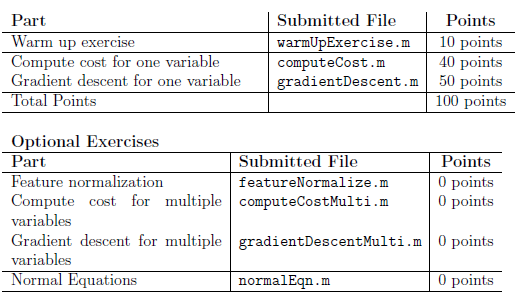

You are allowed to submit your solutions multiple times, andgit

 we will take only the highest score into consideration.